kai =   KernelDistribution

    Kernel = epanechnikov
    Bandwidth = 0.01226
    Support = unbounded


times =     1.0000    1.0010    1.0020    1.0030    1.0040    1.0050    1.0060    1.0070    1.0080    1.0090    1.0100    1.0110    1.0120    1.0130    1.0140    1.0150    1.0160    1.0170    1.0180    1.0190    1.0200    1.0210    1.0220    1.0230    1.0240    1.0250    1.0260    1.0270    1.0280    1.0290    1.0300    1.0310    1.0320    1.0330    1.0340    1.0350    1.0360    1.0370    1.0380    1.0390    1.0400    1.0410    1.0420    1.0430    1.0440    1.0450    1.0460    1.0470    1.0480    1.0490


values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


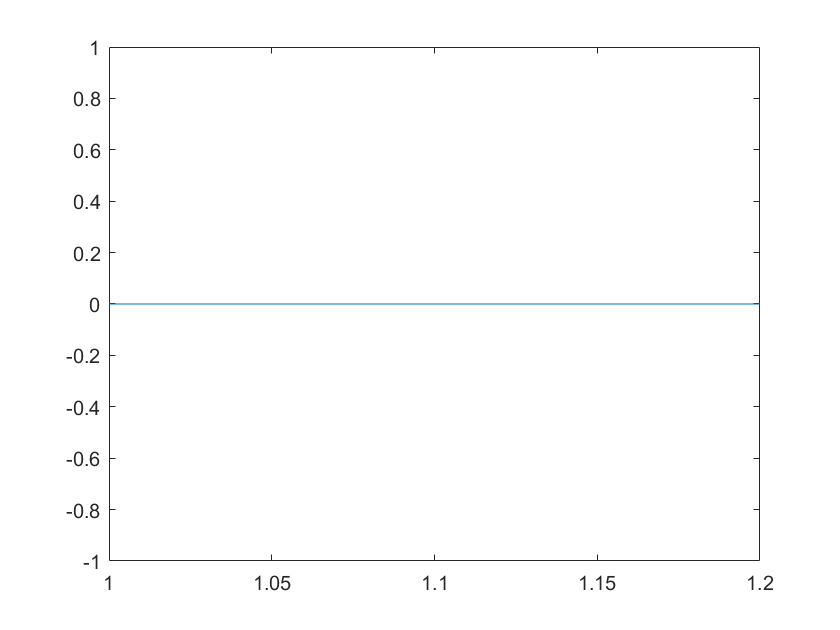

ans = 0

pd = fitdist(tt10','Kernel','Kernel','epanechnikov')

times = 0:0.001:1.5
values = pdf(pd,times)
plot(times,values)
hold on
%values = pdf(p10,times)
plot(times,p10)

x = [0 0.05:0.01:0.1 0.15:0.05:0.95]; %the amplitude values
y1 = 0:0.01:2;
Z = [kai0' kai1' kai_1' kai_2' kai_3' kai_4' kai2' kai3' kai4' kai6' kai5' kai7' kai8' kai9' kai10' kai11' kai12' kai13' kai14' kai15' kai16' kai17' kai18' kai19'];
[X,Y] = meshgrid(x,y1);
figure
%contourf(X,Y,Z,50, 'edgecolor', 'none')
plot3(X,Y,Z)
%shading interp;
%colormap jet;
%xlim([0,0.95])
%ylim([0.2,1.2])
%xlabel ('A','interpreter','latex')
%ylabel ('$\tau$','interpreter','latex')
%a = colorbar;
%a.Label.String = '\rho';